clc
clear
close all

% Order of ideal function
N = 3

N = 3


% Number of microphones M > N 
%M = N +3
M =7

M = 7


% Steering of main lobe
steerAng =35.01

steerAng = 35.0100

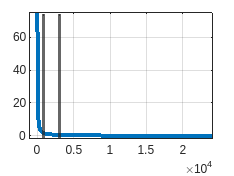

%xs = cosd(steerAng);
xs = sind(steerAng-90);

% Speed of sound (m/s)
%c = 343;  
c = 1496;


% Minimum and maximum frequency
f_min = 0;
f_max = 24e3;

% Signal frequency to design filter (Hz)
f = f_max; % (Invariant)

% Frequency sweep list
freqs = linspace(f_min, f_max, (f_max-f_min)/(100)+1);
freqs(1) = 20;

thetas = linspace(0,2*pi,360);

% Length of array (m)
dmax = 1;

%(c./[4000/2 (4000+14000)/2 (14000+24000)/2])*0.1
plot(freqs,c./freqs, 'LineWidth', 3)
hold on
%plot(ones(length(freqs),1)*1000, linspace(0,c/max(freqs),length(freqs)))
xline(800, 'LineWidth', 2)
xlim([-1000 max(freqs)])
ylim([-2 c/min(freqs)])
xline(3000, 'LineWidth', 2)
grid
hold off


% ULA1Lambda = c/400 % en hel bølgelængde over 3 mikrofoner
% ULA2Lambda = c/1100
% ULA3Lambda = c/10500
% 
% divfactor = 4;
% ULA1 = (0:2).*ULA1Lambda*1/divfactor% en hel bølgelængde over 3 mikrofoner
% ULA2 = [ULA1(2)-ULA2Lambda/divfactor ULA1(2) ULA1(2)+ULA2Lambda/divfactor]
% ULA3 = [ULA1(2)-ULA3Lambda/divfactor ULA1(2) ULA1(2)+ULA3Lambda/divfactor]


ULA1 = linspace(0, dmax, N)

ULA1 =          0    0.5000    1.0000


%ULA1 = (0:2).*0.6
ULA1Offset = ULA1;
%ULA2 = [dmax/2-dmax/4 dmax/2 dmax/2+dmax/4]
ULA2 = [ULA1(2)-ULA1(2)/4 ULA1(2) ULA1(2)+ULA1(2)/4]

ULA2 =     0.3750    0.5000    0.6250


ULA2Offset = ULA2-ULA2(1)

ULA2Offset =          0    0.1250    0.2500


%ULA3 = [dmax/2-dmax/14 dmax/2 dmax/2+dmax/14project-name]
ULA3 = [ULA1(2)-ULA1(2)/12 ULA1(2) ULA1(2)+ULA1(2)/12]

ULA3 =     0.4583    0.5000    0.5417


%ULA3 = [0.7 0.75 0.8 0.85]
ULA3Offset = ULA3-ULA3(1)

ULA3Offset =          0    0.0417    0.0833



micArray = sort(unique([ULA1 ULA2 ULA3]))

micArray =          0    0.3750    0.4583    0.5000    0.5417    0.6250    1.0000


plot(micArray, zeros(length(micArray),1), 'o')
hold on
pbaspect([2 1 1])
set(gca,'YTickLabel',{' '})
grid minor
hold off

%tauULA1 = (micArray([1 ceil(end/2) end])*xs)/c;
tauULA1 = (ULA1Offset*xs)/c;
%tauULA2 = (micArray([2 ceil(end/2) end-1])*xs)/c;
tauULA2 = (ULA2Offset*xs)/c;
%tauULA3 = (micArray([3 ceil(end/2) end-2])*xs)/c;
tauULA3 = (ULA3Offset*xs)/c;

save('DASParams.mat', 'steerAng', 'micArray', 'tauULA1', 'tauULA2', 'tauULA3')


%dfIntegral = zeros(1,length(freqs));
dfalt = zeros(1,length(freqs));
output = zeros(length(freqs),length(thetas));
for b=1:length(freqs)
    %for q=1:length(thetas)
        if freqs(b) <   1700
            outputEach = exp(-1i*2*pi*freqs(b)*(ULA1Offset.*cos(thetas(:))/c+tauULA1));
            dfNum = exp(-1i*2*pi*freqs(b)*(ULA1Offset.*xs/c+tauULA1));
        elseif freqs(b) < 7000
            outputEach = exp(-1i*2*pi*freqs(b)*(ULA2Offset.*cos(thetas(:))/c+tauULA2));
            dfNum = exp(-1i*2*pi*freqs(b)*(ULA2Offset.*xs/c+tauULA2));
        else
            outputEach = exp(-1i*2*pi*freqs(b)*(ULA3Offset.*cos(thetas(:))/c+tauULA3));
            dfNum = exp(-1i*2*pi*freqs(b)*(ULA3Offset.*xs/c+tauULA3));
        end
    %end
    output(b,:) = sum(outputEach,2);
    

    % Approximate integral through trapezoidal
    dfPower = abs(power(output,2));
    dfIntegral = 0.5*(thetas(2)-thetas(1))*(dfPower(b,1)*sin(thetas(1)) + ...
        2*dfPower(b,2:end/2-1)*sin(thetas(2:end/2-1))' + dfPower(b,end/2)*sin(thetas(end/2)));
    dfalt(b) = 10*log10(power(sum(abs(dfNum)),2)/(0.5*dfIntegral));
    %dfalt(b) = 10*log10(power(abs(h'*(exp((-1i*2*pi*freqs(b)*d*(0:M-1).*xs)/c))'),2)/(0.5*dfIntegral(b))) ;
end

%bp = abs(output);
bp = sqrt(power(real(output),2)+power(imag(output),2))/N

bp =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9997    0.9997    0.9997    0.9997    0.9997    0.9998    0.9998    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9997    0.9997    

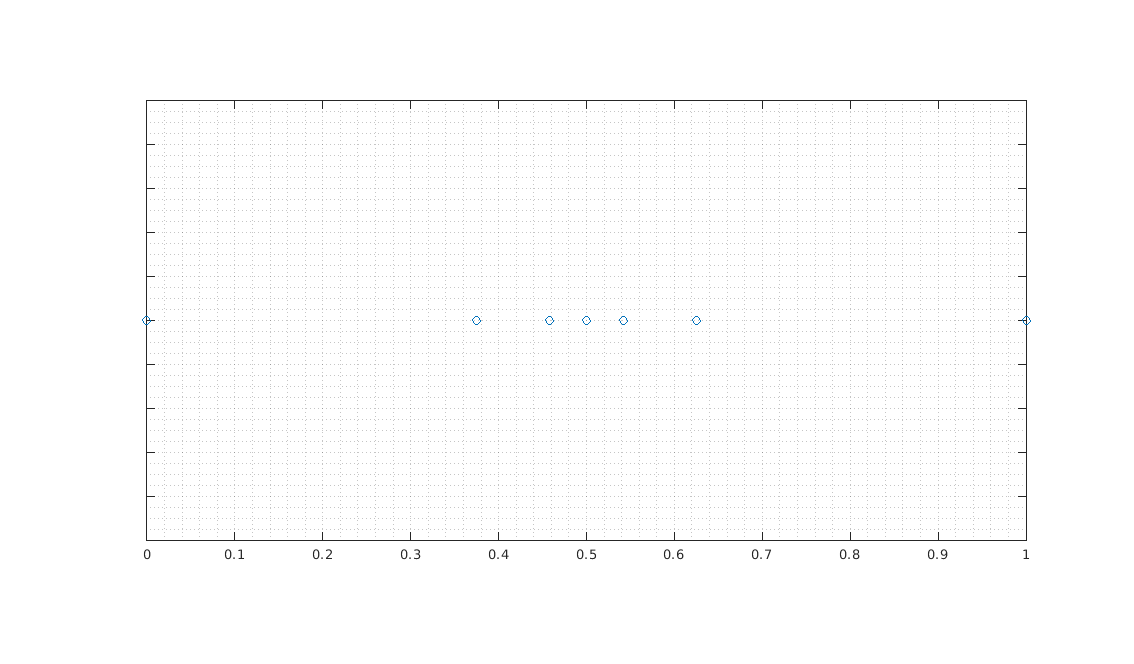

mindB = -50;
logOutput = mag2db(bp);
logOutput(logOutput < mindB) = mindB;

indexHz = find(freqs==9000); % Find design frequency in sweep list
plotVisibility = 'on';

figure(1)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 20]) %21/2-2*2

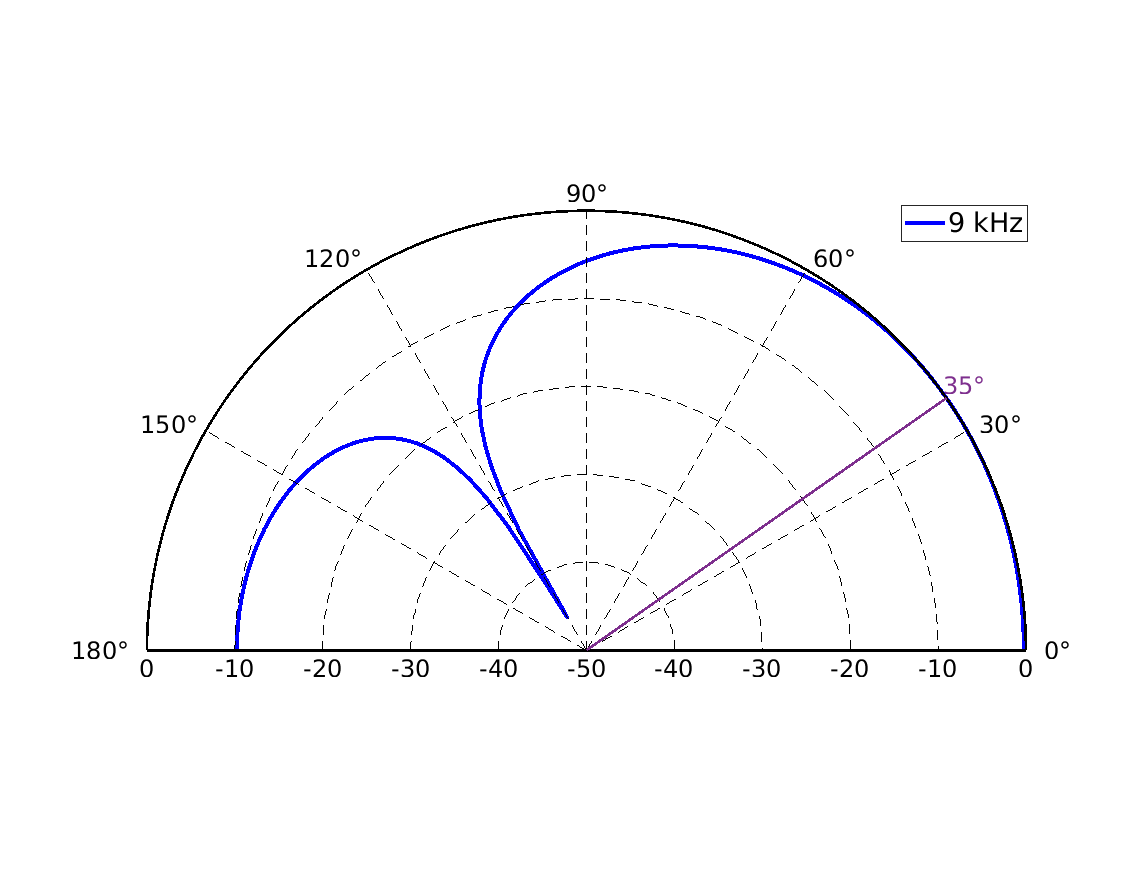

circPlot(freqs(indexHz), thetas, logOutput(indexHz,:), steerAng)

figure(2)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 30 30])

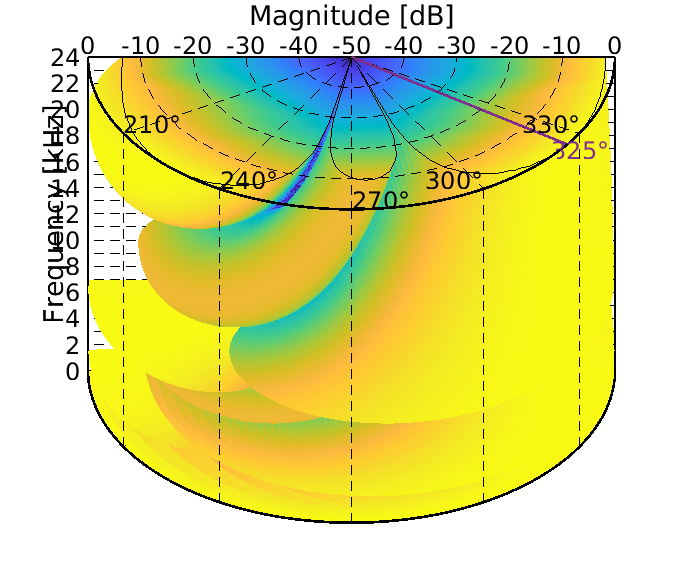

cylindricalPlot(freqs, thetas, logOutput, steerAng)

figure(4)
set(gcf,'Visible',plotVisibility, 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 18])

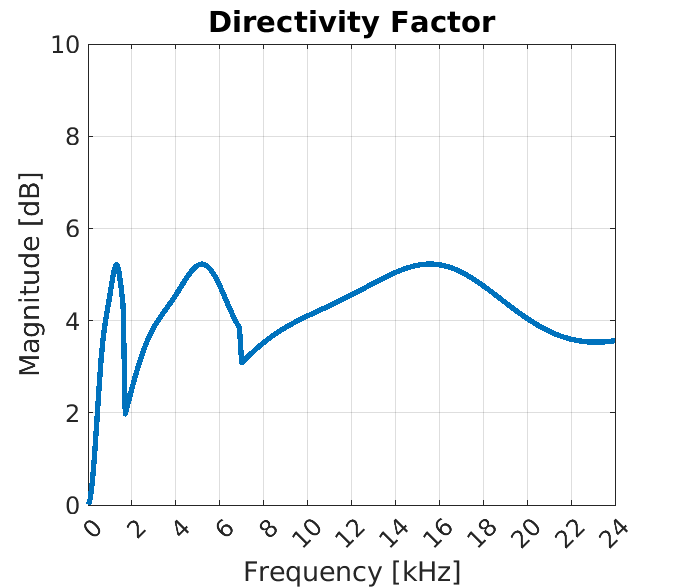

plot(freqs, dfalt, 'LineWidth', 4)
hold on
xlim([0 f_max])
ylim([0 10])
ytickList = linspace(0,10,10+1);
yticks(ytickList(1:2:end))
yticklabels(string(ytickList(1:2:end)))
xtickList = linspace(f_min,f_max,f_max/1000+1);
xticks(xtickList(1:2:end))
xticklabels(string(xtickList(1:2:end)/1000))
ax = gca;
ax.FontSize = 18;
xlabel('Frequency [kHz]', 'FontSize', 20)
ylabel('Magnitude [dB]', 'FontSize', 20)
title('Directivity Factor', 'FontSize', 22)
grid
%legend('M=' + string(Mlist), 'Location', 'northwest')
hold off

%exportgraphics(gcf,'DASDF4N.pdf')